#  Taxi capstone project

## Project overview

Create a new model that predicts demand around Manhattan and the airports. This work will first be reviewed by other data science team members to ensure the model is accurate and likely to generalize. Present work will then present to Mr. Walker and the business team. Create a compelling final report detailing your findings to get the model implemented.

Mr. Walker has asked that your new analysis do the following:

- Focus on four custom regions in Manhattan and the airports (see map below). 

- Predict if demand for taxis is “low,” “medium,” or “high.” 

- Explore revenue (Fare) and cost (Duration and Distance) of each region to see if certain regions of the city are more profitable. 

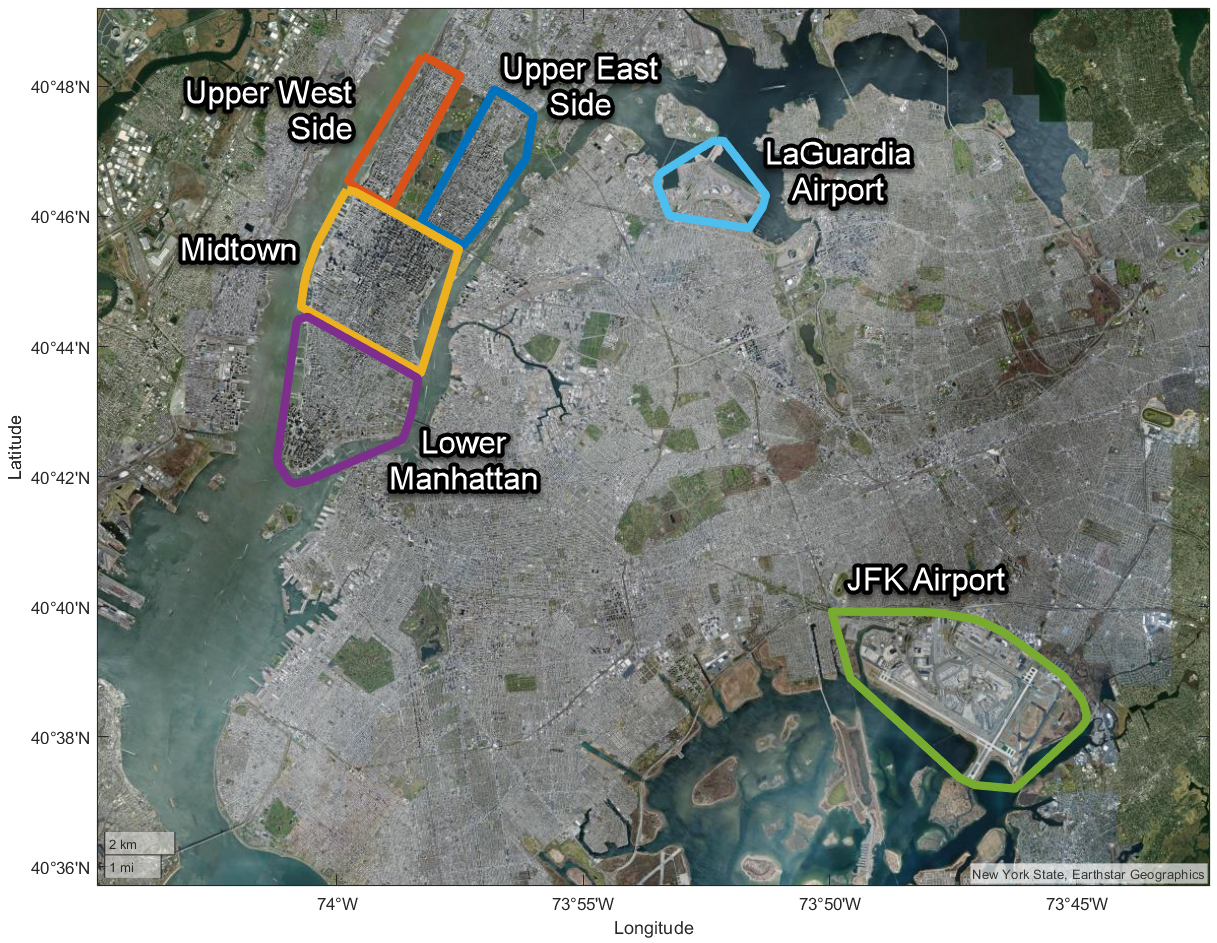

A model that successfully predicts demand will enable Super Taxis to focus on high demand regions and avoid low demand ones, thus improving efficiency and increasing profits.   

clearvars
close all
clc

## Data loading and regions addition

taxiData = [];
for i = 1:12
    if i >= 10
        taxiString = strcat("yellow_tripdata_2015-",num2str(i));
    else
        taxiString = strcat("yellow_tripdata_2015-0",num2str(i));
    end
    taxiData_load = importTaxiDataWithoutCleaning(taxiString);
    taxiData = [taxiData; taxiData_load];
end


### **PickupZone** and **DropoffZone columns**

taxiData = addTaxiZones(taxiData);

taxiData.PickupZone = categorical(taxiData.PickupZone);
taxiData.DropoffZone = categorical(taxiData.DropoffZone);

### **Pickup Region **and **Drop-off Region columns**

taxiRegions = readtable("Taxi Regions and Zones.csv","VariableNamingRule","preserve");
taxiRegions = categorical(taxiRegions{:,:});
stringRegion = categorical(["Lower Manhattan","Midtown","Upper East Side","Upper West Side","JKF Airport","LaGuardia Airport"]);
taxiData.PickupRegion = categorical(zeros(height(taxiData),1));
taxiData.DropoffRegion = categorical(zeros(height(taxiData),1));
for j = 1:width(taxiRegions)
    taxiData.PickupRegion(ismember(taxiData.PickupZone,taxiRegions(:,j))) = stringRegion(j);
    taxiData.DropoffRegion(ismember(taxiData.DropoffZone,taxiRegions(:,j))) = stringRegion(j);
end
taxiData.PickupRegion(taxiData.PickupRegion == "0",:) = "";
taxiData.DropoffRegion(taxiData.DropoffRegion == "0",:) = "";

### Brief dataset summary 

Considering fare and distance

gmedianFare = groupsummary(taxiData,"PickupRegion","median","Fare");
gmedianFare = sortrows(gmedianFare,'median_Fare','ascend')

gmedianFare = 7×3 table
      PickupRegion       GroupCount    median_Fare
    _________________    __________    ___________

    Upper East Side      4.2224e+05        8.5    
    Midtown              1.2961e+06          9    
    Upper West Side      2.6552e+05          9    
    Lower Manhattan      5.8059e+05         10    
    <undefined>          2.2494e+05         10    
    LaGuardia Airport         70720       31.5    
    JKF Airport               62178         52    


medianDistance = groupsummary(taxiData,"PickupRegion","median","Distance");
medianDistance = sortrows(medianDistance,'median_Distance','ascend')

medianDistance = 7×3 table
      PickupRegion       GroupCount    median_Distance
    _________________    __________    _______________

    Upper East Side      4.2224e+05           1.5     
    Midtown              1.2961e+06          1.54     
    Upper West Side      2.6552e+05          1.69     
    <undefined>          2.2494e+05           1.9     
    Lower Manhattan      5.8059e+05             2     
    LaGuardia Airport         70720          9.73     
    JKF Airport               62178         17.53     


medianPassengers = groupsummary(taxiData,"PickupRegion","median","Passengers");
medianPassengers = sortrows(medianPassengers,'median_Passengers','ascend')

medianPassengers = 7×3 table
      PickupRegion       GroupCount    median_Passengers
    _________________    __________    _________________

    Lower Manhattan      5.8059e+05            1        
    Midtown              1.2961e+06            1        
    Upper East Side      4.2224e+05            1        
    Upper West Side      2.6552e+05            1        
    JKF Airport               62178            1        
    LaGuardia Airport         70720            1        
    <undefined>          2.2494e+05            1        


## Data cleaning 

Not all data and features has valid and significative data, in this section whole dataset will be cleaned through following criteria:

- Pickup and dropoff region (only area of interest will be picked);

- Geoscatter plot to analyse if there are some latitude or longitude to exclude;

- Distance

- Fare

Two data summaries will be provided for both uncleaned and cleaned data.

summary(taxiData)

Variables:

    Vendor: 2922266×1 categorical

        Values:

            1    1.3876e+06
            2    1.5347e+06

    PickupTime: 2922266×1 datetime

        Values:

            Min       2015-01-01 00:00:43
            Median    2015-06-20 18:21:55
            Max       2015-12-31 23:59:59

    DropoffTime: 2922266×1 datetime

        Values:

            Min       2015-01-01 00:04:02
            Median    2015-06-20 18:35:14
            Max       2016-01-01 22:10:58

    Passengers: 2922266×1 double

        Values:

            Min          0    
            Median       1    
            Max          9    

    Distance: 2922266×1 double

        Values:

            Min               0
            Median         1.71
            Max       1.468e+07

    PickupLon: 2922266×1 double

        Values:

            Min        -171.8 
            Median    -73.982 
            M

original_height = height(taxiData);

% taxiData_min = taxiData(~(isundefined(taxiData.PickupRegion) & isundefined(taxiData.DropoffRegion)),:);
taxiData_min = taxiData(~(isundefined(taxiData.PickupRegion) | isundefined(taxiData.DropoffRegion)),:);
taxiData_min = taxiData_min(taxiData_min.Distance > 0,:);
taxiData_min = taxiData_min(taxiData_min.Passengers > 0,:);

taxiData.Properties.VariableNames

ans = 1×25 cell array
    {'Vendor'}    {'PickupTime'}    {'DropoffTime'}    {'Passengers'}    {'Distance'}    {'PickupLon'}    {'PickupLat'}    {'RateCode'}    {'HeldFlag'}    {'DropoffLon'}    {'DropoffLat'}    {'PayType'}    {'Fare'}    {'ExtraCharge'}    {'Tax'}    {'Tip'}    {'Tolls'}    {'ImpSurcharge'}    {'TotalCharge'}    {'tzPickupBorough'}    {'tzDropoffBorough'}    {'PickupZone'}    {'DropoffZone'}    {'PickupRegion'}    {'DropoffRegion'}


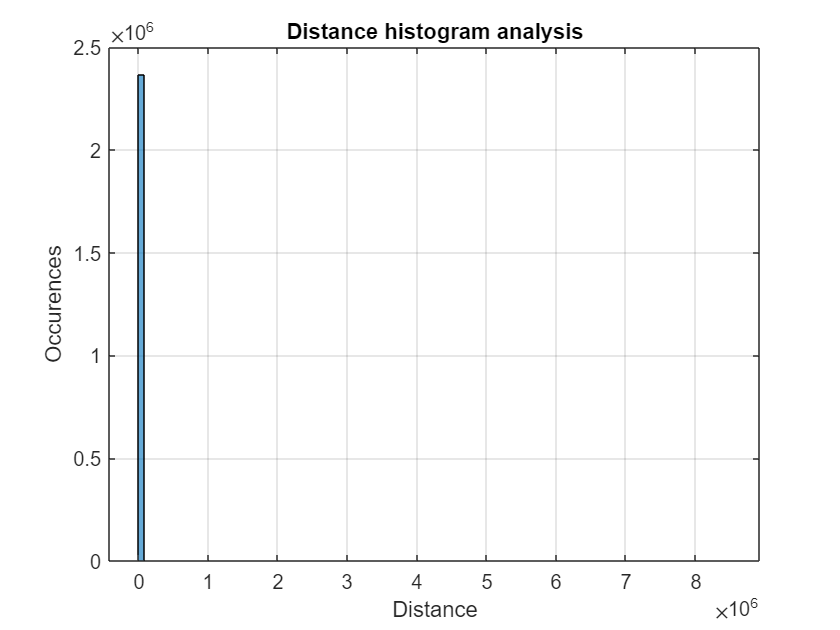

figure("Name","Distance analysis")
    histogram(taxiData_min.Distance,100)
    grid on
    xlabel("Distance")
    ylabel("Occurences")
    title("Distance histogram analysis")

%     xlim([-425000 8925000])
%     ylim([0.00 1.89])
taxiData_min = taxiData_min(taxiData_min.Distance < 23 & taxiData_min.Distance > 0, :);    % Valid distance

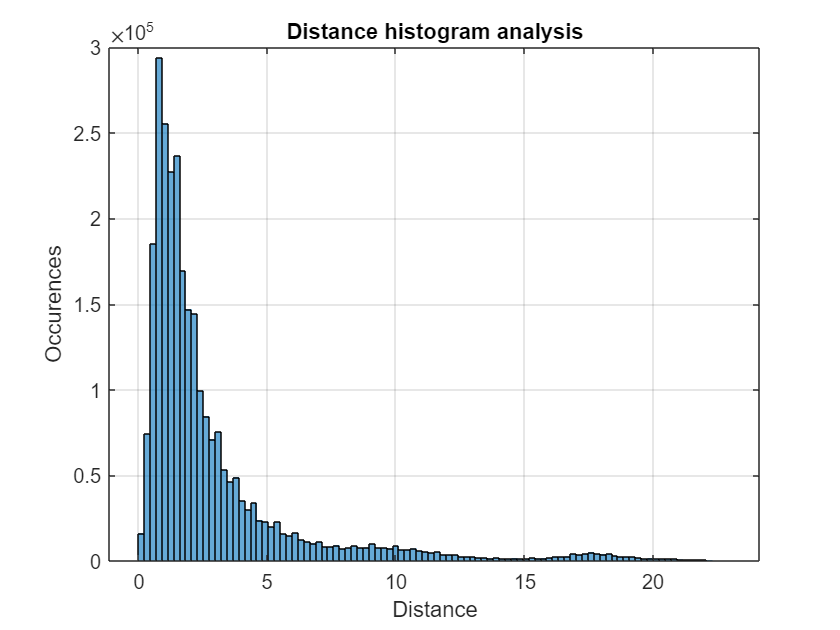

figure("Name","Distance analysis")
    histogram(taxiData_min.Distance,100)
    grid on
    xlabel("Distance")
    ylabel("Occurences")
    title("Distance histogram analysis")

taxiData_min = taxiData_min(taxiData_min.Fare > 2.5 & taxiData_min.Fare < 60, :);    % Valid fare

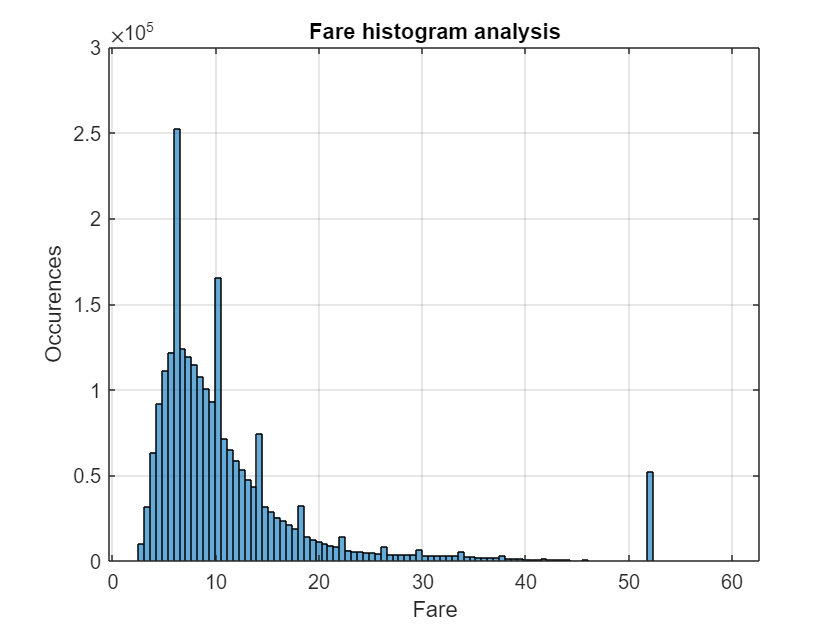

figure("Name","Fare analysis")
    histogram(taxiData_min.Fare,100)
    grid on
    xlabel("Fare")
    ylabel("Occurences")
    title("Fare histogram analysis")

taxiData_min = taxiData_min(taxiData_min.DropoffLat <= 90, :); 

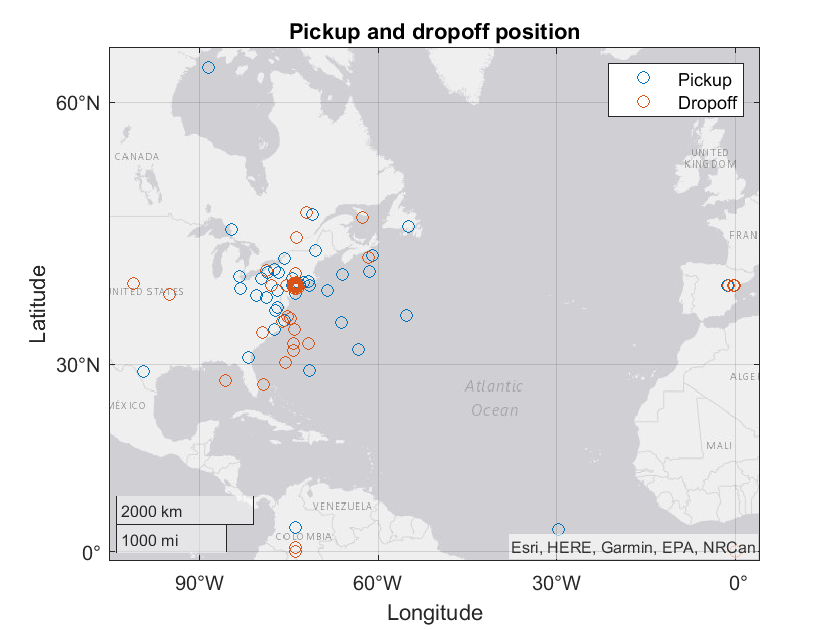

figure("Name","Geoplot Pickup Dropoff")
geoscatter(taxiData_min.PickupLat, taxiData_min.PickupLon)
hold on
geoscatter(taxiData_min.DropoffLat, taxiData_min.DropoffLon)
title ("Pickup and dropoff position")
legend("Pickup","Dropoff")

From previous figure is clear that there are undesired latitude and longitude couples. The idea is to clean data using only desired latiture and longitude. 

% taxiData_min = taxiData_min(taxiData_min.PickupLat > 40.35 & ...
%     taxiData_min.PickupLat < 40.55 & ...
%     taxiData_min.PickupLon < -73.30 & ...
%     taxiData_min.PickupLon > -74.20,:);

taxiData_min_geo = taxiData_min(taxiData_min.PickupLat > 40.62 & ...
    taxiData_min.PickupLat < 40.87 & ...
    taxiData_min.PickupLon < -73.75 & ...
    taxiData_min.PickupLon > -74.04,:);

taxiData_min_geo = taxiData_min_geo(taxiData_min_geo.DropoffLat > 40.635 & ...
    taxiData_min_geo.DropoffLat < 40.87 & ...
    taxiData_min_geo.DropoffLon < -73.75 & ...
    taxiData_min_geo.DropoffLon > -74.04,:);

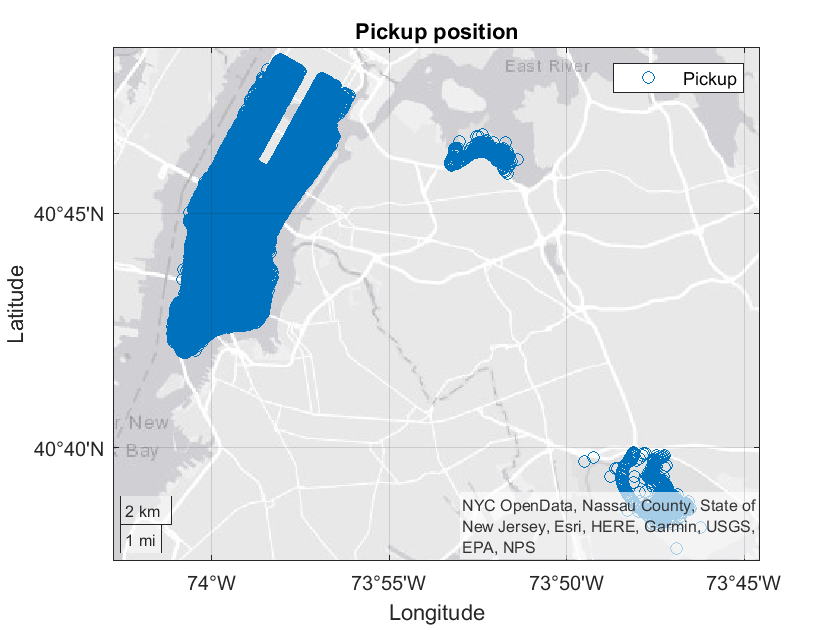

figure("Name","Geoplot Pickup")
geoscatter(taxiData_min_geo.PickupLat, taxiData_min_geo.PickupLon)
title ("Pickup position")
legend("Pickup")

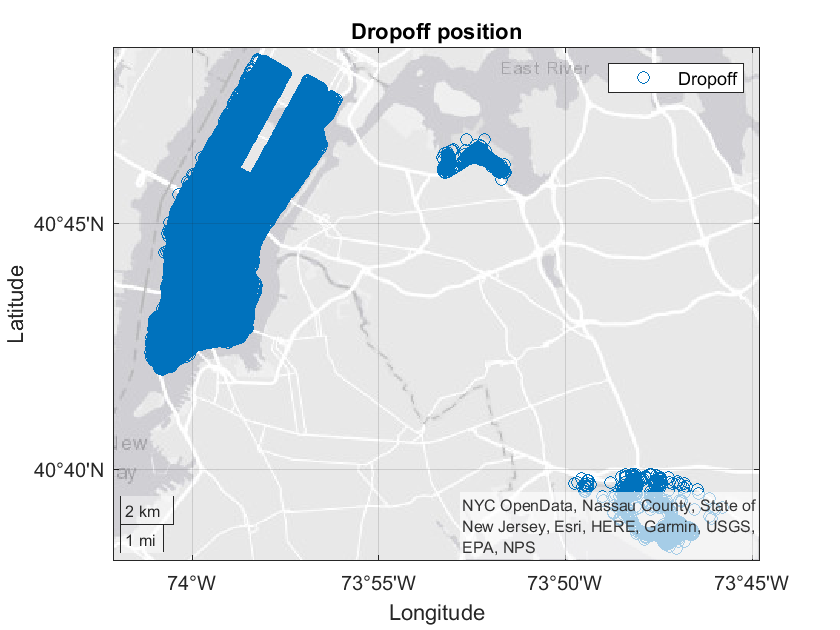

figure("Name","Geoplot Dropoff")
geoscatter(taxiData_min_geo.DropoffLat, taxiData_min_geo.DropoffLon)
title ("Dropoff position")
legend("Dropoff")

taxiData_min_tools = taxiData_min_geo(taxiData_min_geo.Tolls < 50,:);

format short
summary_drop = groupcounts(taxiData_min_tools,"DropoffRegion");
sortrows(summary_drop,'GroupCount','descend')

ans = 6×3 table
      DropoffRegion      GroupCount    Percent
    _________________    __________    _______

    Midtown              1.1664e+06     49.435
    Lower Manhattan      5.0753e+05     21.511
    Upper East Side      3.9995e+05     16.951
    Upper West Side      2.3077e+05     9.7805
    LaGuardia Airport         33128     1.4041
    JKF Airport               21675    0.91865


summary_pick = groupcounts(taxiData_min_tools,"PickupRegion");
sortrows(summary_pick,'GroupCount','descend')

ans = 6×3 table
      PickupRegion       GroupCount    Percent
    _________________    __________    _______

    Midtown              1.1716e+06    49.657 
    Lower Manhattan      5.0228e+05    21.288 
    Upper East Side      3.7764e+05    16.005 
    Upper West Side      2.2617e+05    9.5859 
    LaGuardia Airport         48468    2.0542 
    JKF Airport               33252    1.4093 


percentages_removed = 100 - (height(taxiData_min_tools)*100)/original_height

percentages_removed = 19.2599

## Grouped summary table

### Region groups

taxiData_min_summary = summarizedTable(taxiData_min);
taxiData_min_summary = taxiData_min_summary(~isnan(taxiData_min_summary.AvgDistance),:);
taxiData_min_summary = taxiData_min_summary(~isnan(taxiData_min_summary.NetPickups),:);
taxiData_min_summary = sortrows(taxiData_min_summary,'Time','ascend');

taxiData_min_summary_table = timetable2table(taxiData_min_summary,'ConvertRowTimes',true);
taxiData_min_summary_table.Properties.VariableNames = ["HourlyBin","AvgDistance","AvgDuration","AvgFare","PickupCount","DropoffCount","NetPickups","Region"];

Summary_table = groupsummary(taxiData_min_summary_table,"Region","max","AvgFare");

stringName = ["Lower Manhattan","Midtown","Upper East Side","Upper West Side","JKF Airport","LaGuardia Airport"];

Summary_iqr = zeros(6,1);
corr_value = zeros(6,1);

for i = 1:6
    Summary_iqr(i) = iqr(taxiData_min_summary_table(taxiData_min_summary_table.Region == stringName(i),:).NetPickups);
    corr_value(i) = corr(taxiData_min_summary_table(taxiData_min_summary_table.Region == stringName(i),:).AvgDistance,...
        minutes(taxiData_min_summary_table(taxiData_min_summary_table.Region == stringName(i),:).AvgDuration));
end
Summary_iqr

Summary_iqr =     13
    20
    18
    13
     5
     8


corr_value

corr_value =     0.0726
    0.0809
   -0.0040
    0.0728
    0.0776
    0.1046


## Response variable definition

### Response variable creation

Since the net pickups for each reagion have been already computed, in order to use a classification model (easier to understand respect to regression one), the idea is toconvert net pickups to a categorical feature, ’Demand’, and use it as the response variable for the classification model. To create *Demand*, net pickup values will be change to categorical values according to the following definitions:

·        Net Pickups < 0: ‘Low’ 

·        0 <= Net Pickups < 15: ‘Medium’

·        Net Pickups >= 15: ‘High’ 

for i = 1:height(taxiData_min_summary_table)
    if taxiData_min_summary_table.NetPickups(i) < 0
        taxiData_min_summary_table.Demand(i) = "Low";
    elseif taxiData_min_summary_table.NetPickups(i) >= 0 && taxiData_min_summary_table.NetPickups(i) < 15
        taxiData_min_summary_table.Demand(i) = "Medium";
    elseif taxiData_min_summary_table.NetPickups(i) >= 15
        taxiData_min_summary_table.Demand(i) = "High";
    else
        taxiData_min_summary_table.Demand(i) = "Undefined";
    end
end
taxiData_min_summary_table.Demand = categorical(taxiData_min_summary_table.Demand);

Demand categories are balanced because *Medium *category is the most common. SPECIFICARE MEGLIO

countcategory = countcats(taxiData_min_summary_table.Demand)';
categoriesnum = categories(taxiData_min_summary_table.Demand)';
array2table(countcategory,"VariableNames",categoriesnum,"RowNames","Count:")

ans = 1×3 table
              High     Low     Medium
              ____    _____    ______

    Count:    4142    22471    24230 


## Evaluating features

Before training the model is important to understand which features are important and which are redundant or with less information.

First of all, whole vector must be scaled in order to analyse and compare data on the same scale, otherwise conclusion could be not consistent. In order to scale data, following code will be used:

By this, through mean and range, the vector will be standardised (like min/max function in Python).

### Split the dataset into a training set and a test set

In order to reproduce following split multiple times, *rng* variable will be set to default. By this the starting point will be the same each time.

In order to correclty split the whole dataaset, *cvpartition *function will be used (80/20 partition).

rng default

taxiPartition = cvpartition(height(taxiData_min_summary_table),"HoldOut",0.2);

taxiTestIdx = test(taxiPartition);
taxiTest = taxiData_min_summary_table(taxiTestIdx,:);

taxiTrainIdx = training(taxiPartition);
taxiTrain = taxiData_min_summary_table(taxiTrainIdx,:);

disp(strcat("Dataset dimension: ", num2str(height(taxiData_min_summary_table))))
disp(strcat("Train set dimension: ", num2str(height(taxiTrain))))
disp(strcat("Test set dimension: ", num2str(height(taxiTest))))

summary_test = summary(taxiTest);
summary_train = summary(taxiTrain);

taxiTrain.AvgDurationMin = minutes(taxiTrain.AvgDuration);

Dataset dimension: 50843


taxiData_min_summary_table.AvgDurationMin = minutes(taxiData_min_summary_table.AvgDuration);

Train set dimension: 40675


summary(taxiTrain);

Test set dimension: 10168


varsToScale = ["AvgDistance", "AvgDurationMin", "AvgFare", "PickupCount", "DropoffCount", "NetPickups"];
taxiWHOLEData_scaled = taxiData_min_summary_table{:,varsToScale};
taxiWHOLEData_scaled = (taxiWHOLEData_scaled-mean(taxiWHOLEData_scaled))./range(taxiWHOLEData_scaled);
taxiWHOLEData_scaled = array2table(taxiWHOLEData_scaled,'VariableNames',varsToScale);

varsToScale = ["AvgDistance", "AvgDurationMin", "AvgFare", "PickupCount", "DropoffCount", "NetPickups"];
taxiData_scaled = taxiTrain{:,varsToScale};

Variables:

    HourlyBin: 40675×1 datetime

        Values:

            Min       2015-01-01 00:00:00
            Median    2015-07-03 01:00:00
            Max       2015-12-31 23:00:00

    AvgDistance: 40675×1 double

        Values:

            Min          0.01 
            Median     2.9005 
            Max          22.8 

    AvgDuration: 40675×1 duration

        Values:

            Min       00:00:52
            Median    00:14:57
            Max       23:16:44

    AvgFare: 40675×1 double

        Values:

            Min             3 
            Median     12.489 
            Max            54 

    PickupCount: 40675×1 double

        Values:

            Min           0   
            Median       28   
            Max         310   

    DropoffCount: 40675×1 double

        Values:

            Min           0   
            Median       27   
            Max       

taxiData_scaled = (taxiData_scaled-mean(taxiData_scaled))./range(taxiData_scaled);
taxiData_scaled = array2table(taxiData_scaled,'VariableNames',varsToScale);
summary(taxiData_scaled)

tiledlayout(length(varsToScale),2);
for i = 1:length(varsToScale)
    nexttile;
    histogram(taxiData_min_summary_table.(varsToScale{i}),15);
    title(varsToScale{i})
    nexttile;
    histogram(taxiWHOLEData_scaled{:,i},15,"BinLimits",[-0.5 0.5])
    title("Scaled "+varsToScale{i})

Variables:

    AvgDistance: 40675×1 double

        Values:

            Min       -0.27337
            Median    -0.14653
            Max        0.72663

    AvgDurationMin: 40675×1 double

        Values:

            Min        -0.014695
            Median    -0.0045981
            Max           0.9853

    AvgFare: 40675×1 double

        Values:

            Min       -0.35314
            Median    -0.16707
            Max        0.64686

    PickupCount: 40675×1 double

        Values:

            Min        -0.14987
            Median    -0.059544
            Max         0.85013

    DropoffCount: 40675×1 double

        Values:

            Min        -0.1508
            Median    -0.06314
            Max         0.8492

    NetPickups: 40675×1 double

        Values:

            Min        -0.47066
            Median    0.0058138
            Max         0.52934



end

The transformation used above also centers the features so that they all have a mean value of 0. While mean-centering is not necessary for the purposes of variance thresholding, it does make the distributions easier to compare visually.

### Compute variance

The next step is to compute the variance using the `var` function. Sorting the features by variance makes comparison easier, as does displaying them in a `table`. 

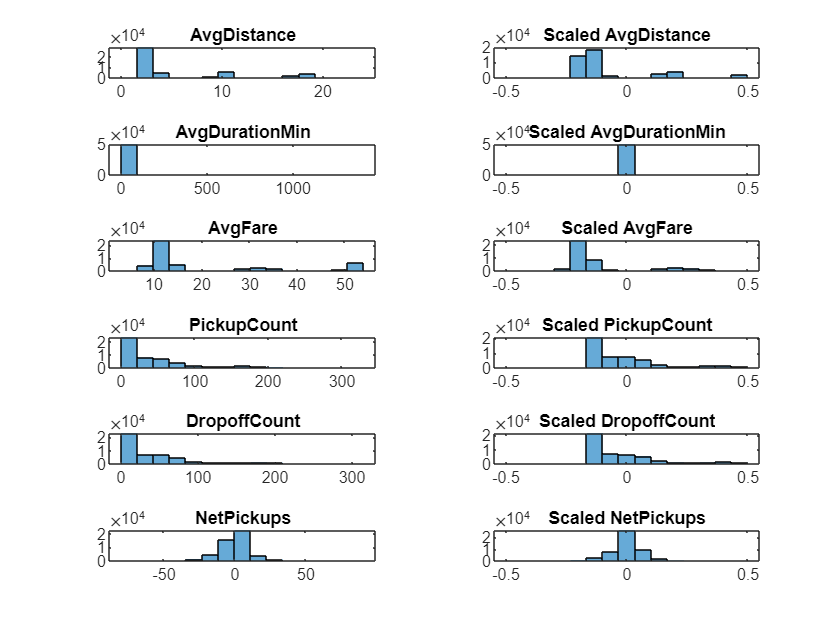

varValue = var(taxiWHOLEData_scaled{:,:});
[varValue,idx] = sort(varValue,"descend");
array2table(varValue,"VariableNames",varsToScale(idx),"RowNames","Variance:")

#### Compare the predictor variances

While scaled predictor variances can be compared directly, it's also common to convert them into proportions so it's easier to see what proportion of variance you lose by discarding a given feature, or alternatively, how much of the total variance is preserved by the features you retain. Additionally, since proportions are consistent across different datasets, this can help you make consistent choices for your thresholds. For example, you might decide for a particular model to keep all features that account for at least 10% of the variance, or to discard as many low-variance features as possible while making sure that at least 90% of the total variance is retained. Run the code below to visualize the variance proportions by feature.

varValue = varValue/sum(varValue);
figure;
bar(varValue);

ans = 1×6 table
                 AvgFare     AvgDistance    DropoffCount    PickupCount    NetPickups    AvgDurationMin
                 ________    ___________    ____________    ___________    __________    ______________

    Variance:    0.086557     0.063214        0.032114       0.028223      0.0053917       0.00023837  


hold on; box on; grid on;
plot(varValue,"r.-","LineWidth",2,"MarkerSize",20);
hold off;
set(gca,"Xtick",1:length(varsToScale),"XTickLabel",varsToScale(idx));
title("Variance proportion by feature")
xlabel("Feature")
ylabel("Variance proportion amount")

### Compute correlation

gplotmatrix(taxiWHOLEData_scaled{:,:},[],[],[],[],[],[],[],varsToScale,varsToScale);

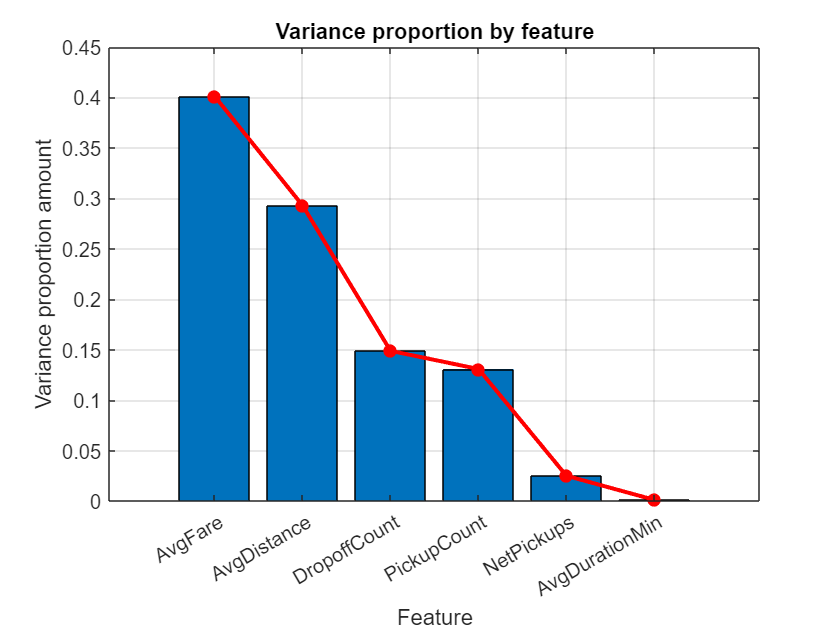


format shortE

Type = "Pearson";


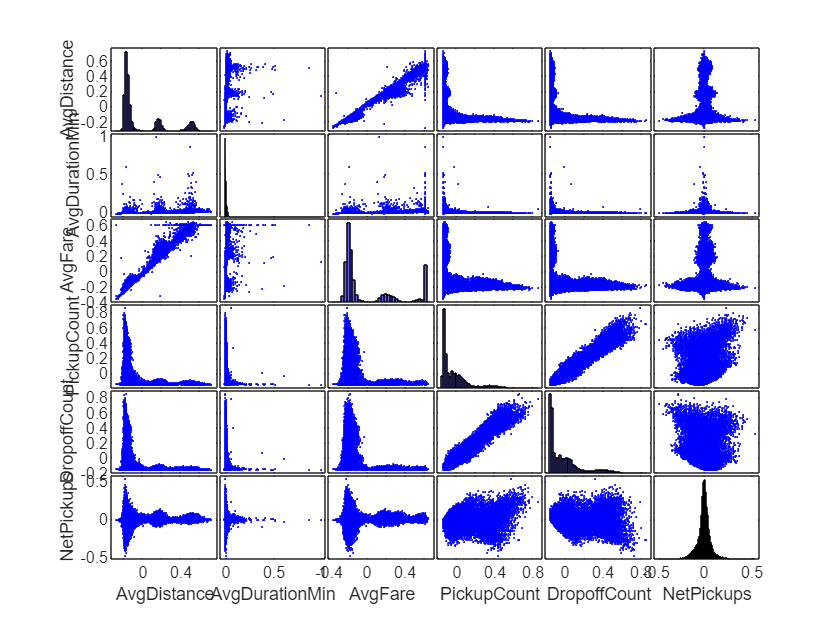

figure('Color',[1 1 1],'Name','Dataset visualization - Correpation and pValue')
[Correlation, pValue] = corrplot(taxiWHOLEData_scaled,...
    Type=Type, ...

    TestR="on", ...
    VarNames = ["ADist", "ADur", "AFare", "Pickup", "Dropoff", "Net"])

### Considerations

REMOVE AVG DURATION MIN

taxiData_DayHourlyBin = day(taxiData_min_summary_table.HourlyBin);

[~,~,p] = crosstab(categorical(taxiData_DayHourlyBin),taxiData_min_summary_table.Demand)
anova = anova1(taxiData_DayHourlyBin,taxi_table.Demand)

importHolidays

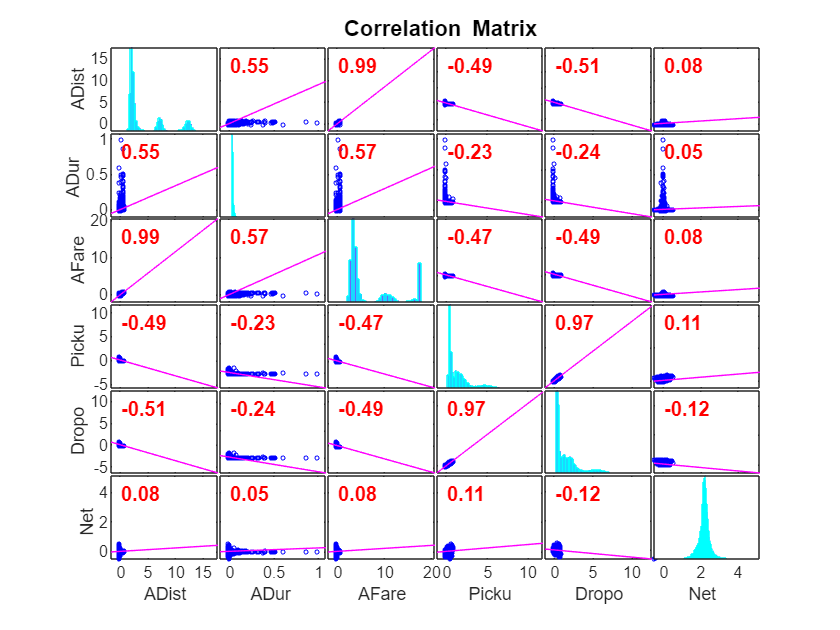

Correlation = 6×6 table
                ADist          ADur           AFare          Picku          Dropo          Net     
             ___________    ___________    ___________    ___________    ___________    ___________

    ADist     1.0000e+00     5.5046e-01     9.9340e-01    -4.9454e-01    -5.1157e-01     7.8951e-02
    ADur      5.5046e-01     1.0000e+00     5.6511e-01    -2.2559e-01    -2.3622e-01     4.8644e-02
    AFare     9.9340e-01     5.6511e-01     1.0000e+00    -4.7095e-01    -4.8842e-01     8.0701e-02
    Picku    -4.9454e-01    -2.2559e-01    -4.7095e-01     1.0000e+00     9.7438e-01     1.0595e-01
    Dropo    -5.1157e-01    -2.3622e-01    -4.8842e-01     9.7438e-01     1.0000e+00  

pValue = 6×6 table
               ADist         ADur          AFare          Picku          Dropo          Net     
             __________    __________    __________    ___________    ___________    ___________

    ADist    1.0000e+00    0.0000e+00    0.0000e+00     0.0000e+00     0.0000e+00     4.1707e-71
    ADur     0.0000e+00    1.0000e+00    0.0000e+00     0.0000e+00     0.0000e+00     5.0619e-28
    AFare    0.0000e+00    0.0000e+00    1.0000e+00     0.0000e+00     0.0000e+00     3.2056e-74
    Picku    0.0000e+00    0.0000e+00    0.0000e+00     1.0000e+00     0.0000e+00    8.0238e-127
    Dropo    0.0000e+00    0.0000e+00    0.0000e+00     0.0000e+00     1.0000e+00    1.9369e-163
    

taxiData_min_summary_table.Date = datetime(year(taxiData_min_summary_table.HourlyBin),month(taxiData_min_summary_table.HourlyBin),day(taxiData_min_summary_table.HourlyBin));

taxiData_min_summary_table.isHoliday = ismember(taxiData_min_summary_table.Date,BankHolidays.Date);

[~,~,p] = crosstab(taxiData_min_summary_table.Demand,taxiData_min_summary_table.isHoliday)

p =    8.4632e-01


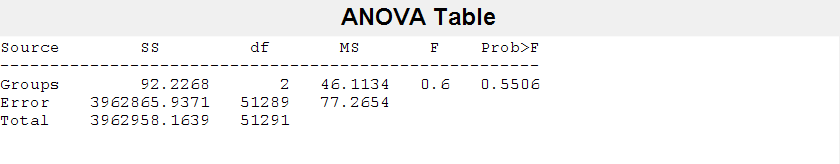

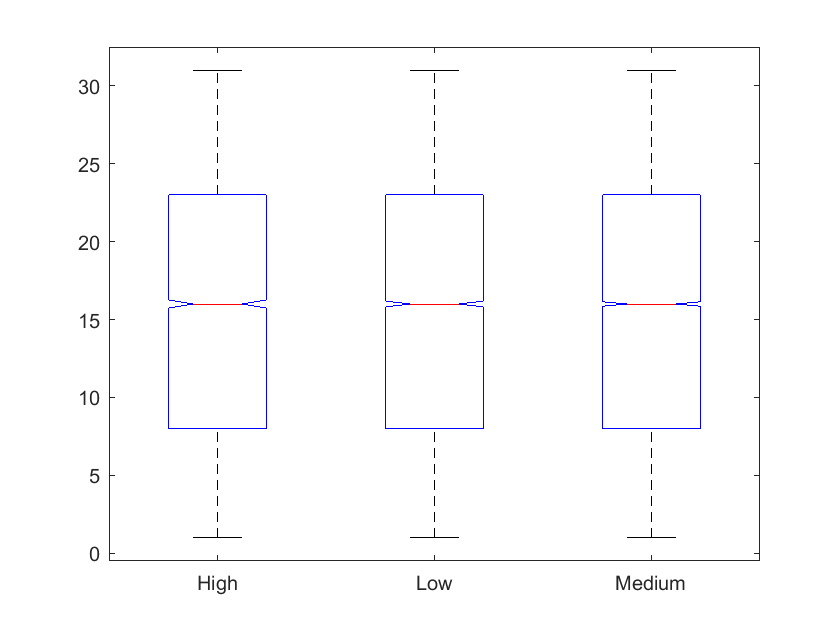

anova =    5.5056e-01


taxiData_scaled.AvgDurationMin = [];

taxiData_scaled.Day = day(taxiTrain.HourlyBin);
taxiData_scaled.Month = month(taxiTrain.HourlyBin);
taxiData_scaled.Hour = hour(taxiTrain.HourlyBin);
taxiData_scaled.Region = taxiTrain.Region;
taxiData_scaled.Demand = taxiTrain.Demand;
taxiTrain.Date = datetime(year(taxiTrain.HourlyBin),month(taxiTrain.HourlyBin),day(taxiTrain.HourlyBin));
taxiData_scaled.isHoliday = ismember(taxiTrain.Date,BankHolidays.Date);

p =    1.3325e-06


## Model train

clear taxiTest_class
taxiTest_class = table();
taxiTest_class.Day = day(taxiTest.HourlyBin);
taxiTest_class.Month = month(taxiTest.HourlyBin);
taxiTest_class.Hour = hour(taxiTest.HourlyBin);

varsToScale = ["AvgDistance", "AvgFare", "PickupCount", "DropoffCount", "NetPickups"];
taxiDataTest_scaled = taxiTest{:,varsToScale};
taxiDataTest_scaled = (taxiDataTest_scaled-mean(taxiDataTest_scaled))./range(taxiDataTest_scaled);
taxiDataTest_scaled = array2table(taxiDataTest_scaled,'VariableNames',varsToScale);

taxiTest_class.PickupCount = taxiDataTest_scaled.PickupCount;
taxiTest_class.DropoffCount = taxiDataTest_scaled.DropoffCount;
taxiTest_class.AvgDistance = taxiDataTest_scaled.AvgDistance;
taxiTest_class.AvgFare = taxiDataTest_scaled.AvgFare;
taxiTest_class.NetPickups = taxiDataTest_scaled.NetPickups;
taxiTest_class.HourlyBin = taxiTest_class.Day;

taxiTest_class.Region = taxiTest.Region;
taxiTest_class.Demand = taxiTest.Demand;
taxiTest.Date = datetime(year(taxiTest.HourlyBin),month(taxiTest.HourlyBin),day(taxiTest.HourlyBin));
taxiTest_class.isHoliday = ismember(taxiTest.Date,BankHolidays.Date);

yfit = trainedModelCostMatrixMod.predictFcn(taxiTest_class);
[t,a] = cMetrics(taxiTest_class.Demand,yfit)

taxiTest_prediction = taxiTest_class;
taxiTest_prediction.Fit = yfit;

taxiTest_prediction_low = taxiTest_prediction(taxiTest_prediction.Fit == "Low",:);
taxiTest_prediction_medium = taxiTest_prediction(taxiTest_prediction.Fit == "Medium",:);
taxiTest_prediction_high = taxiTest_prediction(taxiTest_prediction.Fit == "High",:);

taxiTest_prediction_low = taxiTest_prediction(taxiTest_prediction.Fit == "Low" & ...
    taxiTest_prediction.Day == 4,:);
taxiTest_prediction_medium = taxiTest_prediction(taxiTest_prediction.Fit == "Medium" & ...
    taxiTest_prediction.Day == 4,:);

Not enough input arguments.

Error in trainClassifier (line 46)
inputTable = trainingData;

taxiTest_prediction_high = taxiTest_prediction(taxiTest_prediction.Fit == "High" &...
    taxiTest_prediction.Day == 4,:);


Accuracy = 74.67%

t = 5×5 table
              Precision       Recall       Fallout      Specificity        F1    
              __________    __________    __________    ___________    __________

    High      7.8603e-01    4.2453e-01    1.0515e-02    9.8948e-01     5.5130e-01
    Low       7.7826e-01    6.7638e-01    1.5484e-01    8.4516e-01     7.2375e-01
    Medium    7.2198e-01    8.7015e-01    2.9844e-01    7.0156e-01     7.8917e-01
    Avg       7.6209e-01    6.5702e-01    1.5460e-01    8.4540e-01     6.8807e-01
    WgtAvg    7.5239e-01    7.4666e-01    2.1045e-01    7.8955e-01     7.4019e-01


a =    7.4666e-01


Accuracy = 65.66%

figure("Name","Prediction analysis")
    plot3(categorical(taxiTest_prediction_low.Region),taxiTest_prediction_low.Hour,taxiTest_prediction_low.Fit,'bo')
    hold on
    plot3(categorical(taxiTest_prediction_medium.Region),taxiTest_prediction_medium.Hour,taxiTest_prediction_medium.Fit,'go')
    plot3(categorical(taxiTest_prediction_high.Region),taxiTest_prediction_high.Hour,taxiTest_prediction_high.Fit,'r*',LineWidth=2)
    grid on
    xlabel("Region")
    ylabel("Hour")
    zlabel("Demand")
    title("Region taxi demand per hour on Dec 4th")
    legend("low","medium","high")

taxiTest_prediction_high_SDate = taxiTest_prediction_high(taxiTest_prediction_high.Day == 10 & ...
    taxiTest_prediction_high.Month == 4 & ...
    taxiTest_prediction_high.Hour == 6,:);
disp(taxiTest_prediction_high_SDate.Region)
disp(taxiTest_prediction_high_SDate.Hour)

figure("Name","Prediction analysis")
    plot3(categorical(taxiTest_prediction_high.Region),taxiTest_prediction_high.Day,taxiTest_prediction_high.Month,'bo')
    grid on
    hold on
    xlabel("Region")
    ylabel("Day")
    zlabel("Month")
    title("Region with HIGH taxi demand per date")

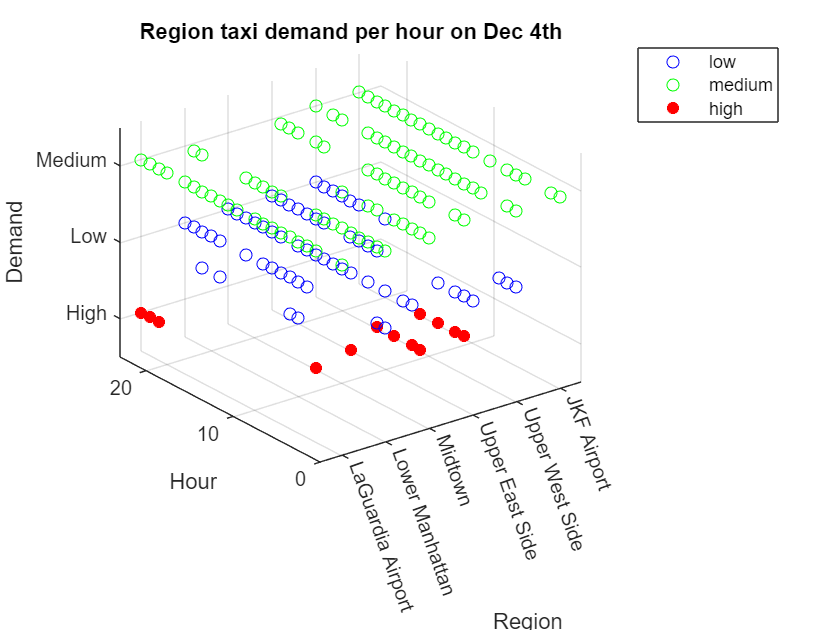

%save taxiDatamat2408.mat

function taxiData_min_summary = summarizedTable(taxiData_min)
    % "Lower Manhattan","Midtown","Upper East Side","Upper West Side","JKF Airport","LaGuardia Airport"
    taxiData_min_LM = taxiData_min(taxiData_min.PickupRegion == "Lower Manhattan" | taxiData_min.DropoffRegion ==  "Lower Manhattan",:);
    taxiData_min_M = taxiData_min(taxiData_min.PickupRegion == "Midtown" | taxiData_min.DropoffRegion ==  "Midtown",:);

Lower Manhattan


    taxiData_min_UES = taxiData_min(taxiData_min.PickupRegion == "Upper East Side" | taxiData_min.DropoffRegion ==  "Upper East Side",:);

     6



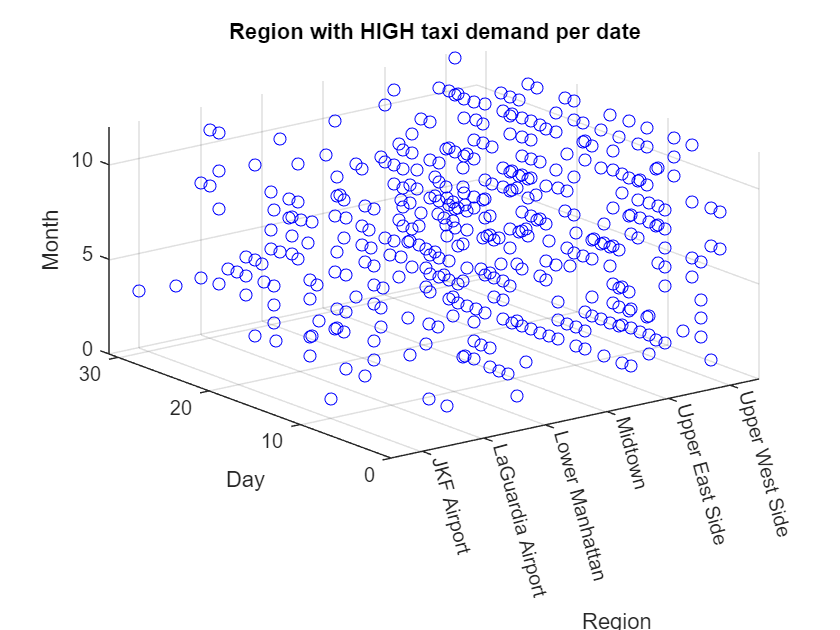

    taxiData_min_UWS = taxiData_min(taxiData_min.PickupRegion == "Upper West Side" | taxiData_min.DropoffRegion ==  "Upper West Side",:);
    taxiData_min_JFK = taxiData_min(taxiData_min.PickupRegion == "JKF Airport" | taxiData_min.DropoffRegion ==  "JKF Airport",:);
    taxiData_min_LG = taxiData_min(taxiData_min.PickupRegion == "LaGuardia Airport" | taxiData_min.DropoffRegion ==  "LaGuardia Airport",:);
    
    taxiData_min_LM = tableRetime(taxiData_min_LM,"Lower Manhattan");
    taxiData_min_M = tableRetime(taxiData_min_M,"Midtown");
    taxiData_min_UES = tableRetime(taxiData_min_UES,"Upper East Side");
    taxiData_min_UWS = tableRetime(taxiData_min_UWS,"Upper West Side");
    taxiData_min_JFK = tableRetime(taxiData_min_JFK,"JKF Airport");

    taxiData_min_LG = tableRetime(taxiData_min_LG,"LaGuardia Airport");

    taxiData_min_summary = vertcat(taxiData_min_LM,taxiData_min_LG,taxiData_min_JFK,taxiData_min_UWS,taxiData_min_UES,taxiData_min_M);
end
    
function [partial_table] = tableRetime(table, name)
    taxiData = timetable(table.PickupTime,table.Distance,(table.DropoffTime-table.PickupTime),table.Fare);
    taxiData = retime(taxiData,'hourly','mean');
    taxiData.Properties.VariableNames = ["AvgDistance","AvgDuration","AvgFare"];

    taxiData = taxiData(~isnan(taxiData.AvgDistance),:);
    
    taxiData_pickup = timetable(table(table.PickupRegion == name,:).PickupTime,table(table.PickupRegion == name,:).PickupTime);
    taxiData_pickup = retime(taxiData_pickup,'hourly','count');
    taxiData_pickup.Properties.VariableNames = "PickupCount";

    taxiData_dropoff = timetable(table(table.DropoffRegion == name,:).DropoffTime,table(table.DropoffRegion == name,:).DropoffTime);
    taxiData_dropoff = retime(taxiData_dropoff,'hourly','count');
    taxiData_dropoff.Properties.VariableNames = "DropoffCount";

    taxiData_pickdrop = outerjoin(taxiData_pickup,taxiData_dropoff);

    taxiData_pickdrop.NetPickups = taxiData_pickdrop.PickupCount - taxiData_pickdrop.DropoffCount;

    taxiData_pickdrop = taxiData_pickdrop(~isnan(taxiData_pickdrop.PickupCount),:);

    partial_table = outerjoin(taxiData,taxiData_pickdrop);
    partial_table.Region = strings(height(partial_table),1);
    partial_table.Region(partial_table.Region == "") = name;

    clear taxiData taxiData_pickup taxiData_dropoff taxiData_pickdrop
end